LK = localization_kalman()

LK =   localization_kalman with properties:

           state: [6×1 double]
             cov: [6×6 double]
     p_tag_front: []
      p_tag_back: []
      anchor_mat: []
               T: []
     UWB_cov_mat: []
     IMU_cov_mat: []
    odom_cov_mat: []
     process_cov: []


LK_wrong = localization_kalman()

LK_wrong =   localization_kalman with properties:

           state: [6×1 double]
             cov: [6×6 double]
     p_tag_front: []
      p_tag_back: []
      anchor_mat: []
               T: []
     UWB_cov_mat: []
     IMU_cov_mat: []
    odom_cov_mat: []
     process_cov: []



LK.T = 1/15;
LK.p_tag_front = [0.2; 0];
LK.p_tag_back  = [-0.2; 0];
LK.anchor_mat = [ 0 10 10  0
               0  0 10 10
               3  3  3  3];
LK.odom_cov_mat = eye(2)*0.1.^2;
LK.UWB_cov_mat = eye(8)*0.1.^2;
LK.IMU_cov_mat = eye(2)*0.1.^2;
LK.process_cov = diag([0 0 0 0.2 0.2 1]).^2;

LK_wrong.T = 1/15;
LK_wrong.p_tag_front = [0.2; 0];
LK_wrong.p_tag_back  = [-0.2; 0];
LK_wrong.anchor_mat = [ 0 10 10  0
               0  0 10 10
               3  3  3  3];
LK_wrong.odom_cov_mat = eye(2)*0.1.^2;
LK_wrong.UWB_cov_mat = eye(8)*0.1.^2*100;
LK_wrong.IMU_cov_mat = eye(2)*0.1.^2;
LK_wrong.process_cov = diag([0 0 0 0.2 0.2 1]).^2;

% meas_UWB = [dist_front_history(:,1); dist_back_history(:,1)];
% [state_c, cov_c] = LK.multi_meas(meas_UWB, [])

kalman_state_hist = [];
kalman_state_hist_wrong = [];

pure_odom = robot_state_history(:,1);
for n = 1:width(dist_front_history)
    meas_UWB = [dist_front_history(:,n); dist_back_history(:,n)];
    meas_IMU = IMU_history(:,n);
    meas_odom = odom_history(:,n);
    [state_c, cov_c] = LK.multi_meas(meas_UWB, meas_IMU, meas_odom);
    kalman_state_hist(:,n) = state_c;

    [state_c_wrong, cov_c_wrong] = LK_wrong.multi_meas(meas_UWB, meas_IMU, meas_odom);
    kalman_state_hist_wrong(:,n) = state_c_wrong;

    [qnext,~] = robot_model(pure_odom(:,n),meas_odom,1/15,[0;0]);
    pure_odom(:,n+1) = qnext;

end


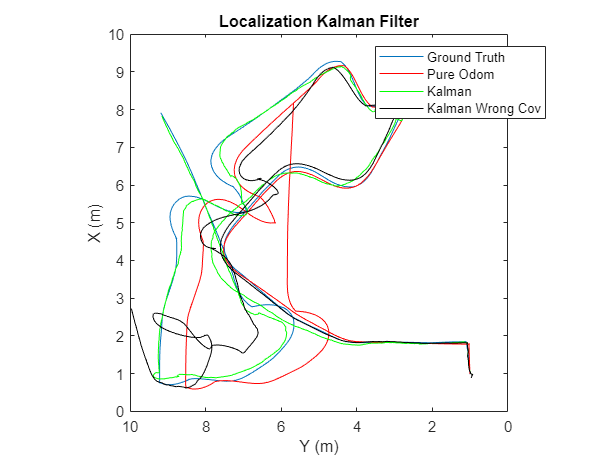

plot(robot_state_history(1,:), robot_state_history(2,:)); hold on
plot(pure_odom(1,:), pure_odom(2,:), 'r');
plot(kalman_state_hist(1,:), kalman_state_hist(2,:), 'g');
plot(kalman_state_hist_wrong(1,:), kalman_state_hist_wrong(2,:), 'k');
hold off
axis square
view(-90,90);
xlabel("X (m)")
ylabel("Y (m)")
title("Localization Kalman Filter")

legend(["Ground Truth", "Pure Odom", "Kalman", "Kalman Wrong Cov"], "Location","northeast")


rms(vecnorm(pure_odom([1 2],1:end-1) - robot_state_history(1:2,:)))

ans = 1.0965

rms(vecnorm(kalman_state_hist([1 2],:) - robot_state_history(1:2,:)))

ans = 0.7498

rms(vecnorm(kalman_state_hist_wrong([1 2],:) - robot_state_history(1:2,:)))

ans = 0.7498


rms(wrapToPi(vecnorm(pure_odom([1 2],1:end-1) - robot_state_history(1:2,:))))

ans = 1.0119

rms(wrapToPi(kalman_state_hist([3],:) - robot_state_history(3,:)))

ans = 2.6364

function a = rms(x)
a = sqrt(mean(x.^2));
end